clear all; close all;


1) Initiate Matlab node

Node = ros2node('Node');

2) Initiate a velocity publisher and a subscriber for the current pose ("/odom") 

velPub = ros2publisher(Node,'/cmd_vel','geometry_msgs/Twist');
odomSub = ros2subscriber(Node,'/odom','nav_msgs/Odometry');

3) Initiate a goal subscriber to the "/goal_pose" topic from RVIZ with a subscriber callback that fills the values of the goal handle. 

goalHandle = PoseHandle();
goalSub = ros2subscriber(Node,'/goal_pose','geometry_msgs/PoseStamped',@(msg) goalCallback(msg,goalHandle));

4) Load the map and display it. Also add the goal pose.

map_img = imread("rst_lab_cropped.pgm");
bwimage = map_img < 100;
bwimage = imrotate(bwimage, 90);
map = binaryOccupancyMap(bwimage, 1/0.05);
map.GridLocationInWorld = [-4.5, -2.8];
inflate(map, 0.05);

figure("Name", "Map");
map.show;
hold on;

%receive the odom message and convert to cood using the helper func
opose = receive(odomSub,15);

[robot_x, robot_y, robot_theta] = OdometryMsg2Pose(opose);
plot(robot_x,robot_y, 'go', 'MarkerSize', 8);   %robot pose is in the odom frame 
quiver(robot_x,robot_y,cos(robot_theta),sin(robot_theta),0.5,'k','LineWidth',1.5); %shows robot heading

fprintf('Robot poses are x=%.3f, y=%.3f, θ=%.3f\n',robot_x,robot_y,robot_theta);

Robot poses are x=5.881, y=4.179, θ=1.687


tfTree  = ros2tf(Node); % Get transformation tree for goal pose
pause(7);

goalPose = goalHandle2goalPose(goalHandle,tfTree); % Transform goalHandle

q = goalPose.pose.orientation;
eul = quat2eul([ q.w, q.x, q.y, q.z ]);  
yaw = eul(1); 

fprintf('Goal poses are x=%.3f, y=%.3f,θ=%.3f\n',goalPose.pose.position.x,goalPose.pose.position.y,yaw);

Goal poses are x=-2.123, y=2.913,θ=1.606


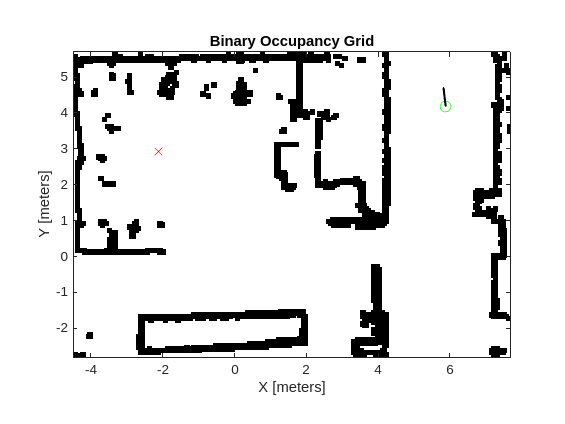

plot(goalPose.pose.position.x,goalPose.pose.position.y, 'rx', 'MarkerSize', 8);

5) Implement PRM and RRT as global path planners for the lab environment regarding the current robot pose.

% generate global plan
global_planner = "RRT";

start_pose = [robot_x,robot_y,robot_theta];
goal_pose = [goalPose.pose.position.x,goalPose.pose.position.y,yaw];

stateSpace = stateSpaceSE2;
stateValidator = validatorOccupancyMap(stateSpace,"Map",map);
stateValidator.Map = map;
stateSpace.StateBounds = [map.XWorldLimits;map.YWorldLimits;[-pi pi]];
stateValidator.ValidationDistance = 0.01;

switch global_planner
    case "PRM"
        disp("Executing PRM...");
 
        planner = plannerPRM(stateSpace,stateValidator,'MaxConnectionDistance',5.0,'MaxNumNodes',200); 
        
        % Visualize roadmap
        show(stateValidator.Map); hold on;
        
        %retrieve graph as a digraph object 
        graph = graphData(planner);
        
        %extract the nodes and edges from the graph  
        nodes = table2array(graph.Nodes);
        edges = table2array(graph.Edges);

        % draw nodes
        plot(nodes(:,1), nodes(:,2), '*b', 'LineWidth', 2);

        % draw edges
        for i = 1:size(edges,1)
            seg = interpolate(stateSpace, nodes(edges(i,1),:), ...
                nodes(edges(i,2),:), 0:0.02:1);
            plot(seg(:,1), seg(:,2), 'b');
        end

        plot(robot_x,robot_y, '*g', 'LineWidth', 3);
        plot(goalPose.pose.position.x,goalPose.pose.position.y, '*r', 'LineWidth', 3);

        % plan path
        [path, solnInfo] = plan(planner,start_pose,goal_pose);

        % visualize path
        if solnInfo.IsPathFound
        % path.States is M×3: [x, y, θ]
        xy = path.States(:,1:2);  
        plot( xy(:,1), xy(:,2), '-', ...
          'Color',      [0.85 0.325 0.098], ...
          'LineWidth',  2 );
        else
            warning('PRM: Path not found');
        end

        hold off;
        plannedPath = path.States;

    case "RRT"
        disp("Executing RRT...");
        planner = plannerRRT(stateSpace,stateValidator);
        planner.MaxIterations = 300;
        planner.MaxConnectionDistance = 0.5;

        % plan
        [path, solnInfo] = plan(planner,start_pose,goal_pose);

        % Visualize
        show(stateValidator.Map); hold on;
        plot(robot_x,robot_y, '*g', 'LineWidth', 3);
        plot(goalPose.pose.position.x,goalPose.pose.position.y, '*r', 'LineWidth', 3);

        % PLot Tree
        plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-');
        % Plot Path
        plot(path.States(:,1),path.States(:,2), 'r-', 'LineWidth', 2);

        plannedPath = path.States;

    otherwise
        error('Unknown global planner: %s', global_planner);
end

Executing RRT...


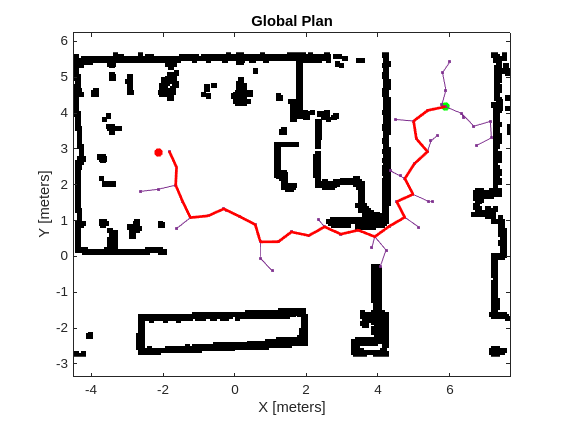


title('Global Plan');
axis equal;

6) Optimize the path

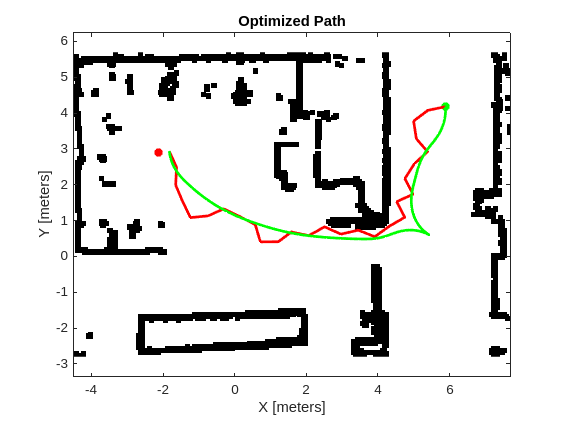

%plannedPath = path.States; already declared in the loops above
options = optimizePathOptions;

%optimization parameters 
options.MinTurningRadius = 1.0;
options.MaxPathStates = 200;
options.ObstacleSafetyMargin = 0.2;
options.WeightVelocity = 1000;
options.NumIteration = 5;
options.MaxSolverIteration = 20;

% Optimize the path generated by the planner.
[optimizedPath, kineticInfo, solutionInfo] = optimizePath(path.States,map,options);

figure;
show(stateValidator.Map); hold on;

% Plot start, end, planned and optimized path
plot(start_pose(1), start_pose(2), '*g', 'LineWidth', 3);
plot(goal_pose(1),  goal_pose(2),  '*r', 'LineWidth', 3);
plot(plannedPath(:,1), plannedPath(:,2), 'r-',  'LineWidth', 2);
plot(optimizedPath(:,1),optimizedPath(:,2),'g-','LineWidth',2);

title('Optimized Path');
axis equal;

drawnow;

7) Implement the teb planner for path following and obstacle avoidance

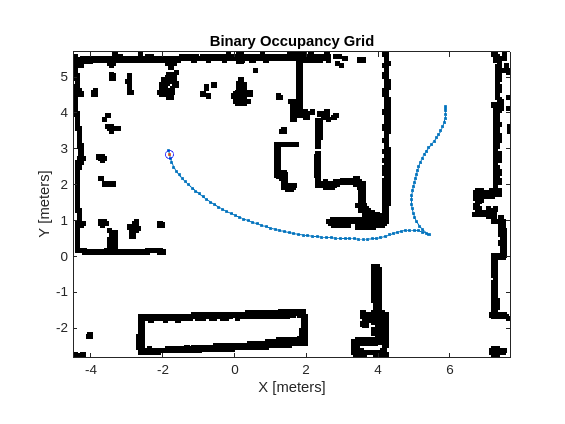

TEB=true;

refpath = optimizedPath;
teb = controllerTEB(refpath, map);
teb.RobotInformation.Shape = "Rectangle";
teb.RobotInformation.Dimension = [0.2 0.2];
teb.LookAheadTime = 5.0;
teb.MaxVelocity = [0.5 1.5];
teb.MaxAcceleration = [0.5 0.5];
teb.ReferenceDeltaTime = 0.3;
teb.ObstacleSafetyMargin = 0.1;

rate = robotics.Rate(5);
goalReached = false;

% Current velocity and pose
curvel = [0 0];
[curpose(1), curpose(2), curpose(3)] = OdometryMsg2Pose(receive(odomSub,10));    


while ~goalReached
    % Update current pose
    opose = receive(odomSub,10);
    [cur_x, cur_y, cur_theta] = OdometryMsg2Pose(opose);

    % Take last velocity
    curvel = curvel;

    % Get next steps from TEB
    [velcmds, tstamps, curpath, info] = step(teb,[cur_x,cur_y,cur_theta], curvel);
    goalReached = info.HasReachedGoal;

    % Visualization (simple)
    clf;
    show(map); hold on;
    plot(refpath(:,1), refpath(:,2), '.-');
    plot(curpath(:,1), curpath(:,2), '.-');
    plot(cur_x, cur_y, 'bo');
    drawnow;

    % Publish cmd_vel
    msg = ros2message("geometry_msgs/Twist");

    msg.linear.x  = velcmds(1,1);
    msg.linear.y  = 0;
    msg.linear.z  = 0;
    msg.angular.x = 0;
    msg.angular.y = 0;
    msg.angular.z = velcmds(1,2);
    
    send(velPub,msg);
    waitfor(rate);
end


disp('Goal reached.');

Goal reached.


### Helper functions you have to implement

function goalCallback(msg,goalHandle)

goalHandle.x = msg.pose.position.x;  %POSE STAMPED
goalHandle.y = msg.pose.position.y;

q = msg.pose.orientation;

%w,x,y,z
eul = quat2eul([q.w, q.x, q.y, q.z]);
goalHandle.theta = eul(1);

disp("Received goal");

end

### Helper functions that are given

function [ x, y, theta ] = OdometryMsg2Pose(poseMsg)
x=poseMsg.pose.pose.position.x; %NAV_MSGS_ODOMETRY
y=poseMsg.pose.pose.position.y;
eul=quat2eul([poseMsg.pose.pose.orientation.w poseMsg.pose.pose.orientation.x  poseMsg.pose.pose.orientation.y poseMsg.pose.pose.orientation.z]);
theta=eul(1);
end

function goalPose = goalHandle2goalPose(goalHandle,tfTree)
pt = ros2message('geometry_msgs/PoseStamped');
pt.header.frame_id = 'map';
pt.pose.position.x = goalHandle.x;
pt.pose.position.y = goalHandle.y;
pt.pose.position.z = 0;
quat = axang2quat([0 0 1 goalHandle.theta]);
pt.pose.orientation.w = quat(1);
pt.pose.orientation.x = quat(2);
pt.pose.orientation.y = quat(3);
pt.pose.orientation.z = quat(4);
goalPose = transform(tfTree,'odom',pt); %transfers to odom frame 

%goalPose = [goalHandle.x,goalHandle.y,goalHandle.theta];
end
